## Problem Symetical Shortcircuit 5

Two synchronous motors having subtransient reactances of *X”**M1* = 0.80 and *X”**M2* = 0.25 per unit, respectively, on a base of 480 V, 2000 kVA are connected to a bus. This motor is connected by a line having a reactance of *X**L* = 0.023 Ω to a bus of a power system. At the power-system bus the short-circuit megavolt-amperes of the power system are 9.6 MVA for a nominal voltage of 480 V. When the voltage at the motor bus is 440 V, neglect load current and find the initial symmetrical rms current in a three-phase fault at the motor bus.  

Created by: Professor Francisco Gonzalez-Longatt, January 2020, [fglongatt@fglongatt.org](mail: fglongatt@fglongatt.org) 

Github: [https://github.com/fglongatt/ElectricalPowerAnalysis](https://github.com/fglongatt/ElectricalPowerAnalysis) 

%% INPUTDATA
XM1 = 0.80      % X1M: Transient reactance of the motor [pu]

XM1 = 0.8000

XM2 = 0.25      % X2M: Subtransient reactance of the motor [pu]

XM2 = 0.2500

Vbase = 480     % Vbase: rated voltage (V)

Vbase = 480

Sbase = 2e6     % Sbase: rated apparent power (VA)

Sbase = 2000000

XL = 0.023;     % XL: Series reactance [Ohms]
Scc = 9.6e6

Scc = 9600000

Vpfpf = 440;    % VPFPF: Voltage at p previous to the fault

The situation is depicted in the equivalent circuit shown below:

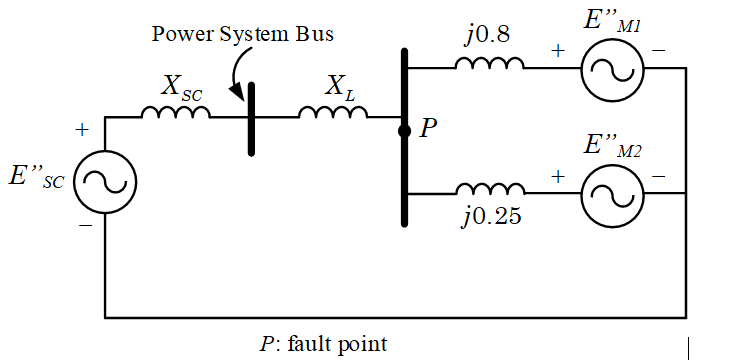

The impedance base (*Z**base*) of the system is calculated using the rated voltage as a base (*V**base*) and the rated power (*S**base*):

Zbase = Vbase^2/Sbase;
fprintf(' Zbase = %5.5f Ohms',Zbase)

 Zbase = 0.11520 Ohms

The line reactance (*X**L*) is transformed into per unit system:

XLpu = XL / Zbase;
fprintf(' XL = %5.5f pu',XLpu)

 XL = 0.19965 pu

The equivalent reactance of the supply system (*X**SC*) is calculated as:

XSC =(Vbase/Vbase)^2*(Sbase/Scc);
fprintf('XSC = %5.5f pu',XSC)

XSC = 0.20833 pu

The Thevenin reactance (*X**th*) is calculated using the following equivalent circuit:

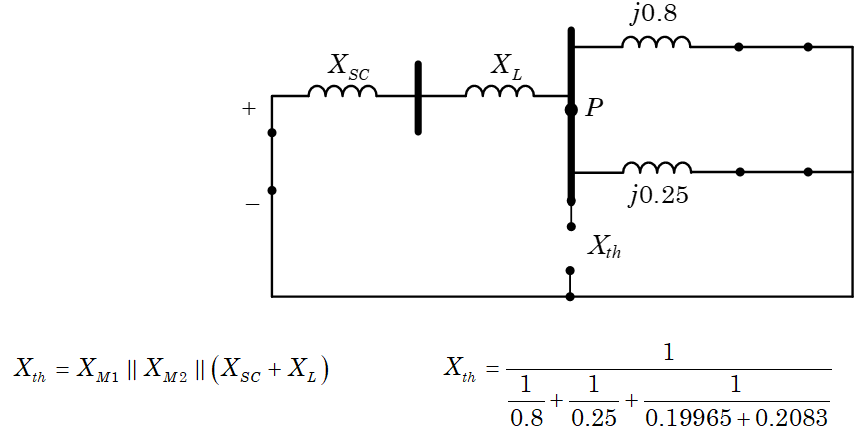

Xth = (1/XM1 + 1/XM2 + 1/(XSC + XLpu) )^-1

Xth = 0.1299

fprintf('Xth = %5.5f pu',Xth)

Xth = 0.12985 pu

The voltage previous to the short circuit is 440 V, the per unit value results:

Vf = Vpfpf / Vbase;
fprintf('Vf = %5.5f pu',Vf)

Vf = 0.91667 pu

Finally, the initial symmetrical rms current (*I”**sc*) in a three-phase fault results:

Icc = Vf / (i*Xth);
fprintf(' Icc = (%5.5f + j%5.5f) pu',real(Icc),imag(Icc))

 Icc = (0.00000 + j-7.05931) pu

fprintf(' Icc = (%5.5f < %5.5f) pu',abs(Icc),angle(Icc)*180/pi)

 Icc = (7.05931 < -90.00000) pu

Calculating the base current (*I**base*):

Ibase = Sbase / (sqrt(3)*Vbase);
fprintf(' Ibase = %5.5f A',Ibase)

 Ibase = 2405.62612 A

The initial symmetrical rms current (*I”**sc*) in a three-phase fault (in Amperes) results:

IfAMP = abs(Icc) * Ibase;
fprintf(' Icc = %5.5f A',IfAMP)

 Icc = 16982.05695 A